## Phase Transition Plot - CoSaMPL 4 levels

clear all;
close all;

N=256;
probability=zeros(15,23); %matrix with number of iterations until signal recovered
sparsities=4:4:60;
m_dim=20:10:240;
for z=1:50
    z
    for k=1:23 %m
        m=m_dim(k);
        for j=1:15%s
            sparsity=sparsities(j);
            A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
            x = zeros(N,1);
            while (nnz(x(1:N/4))<(sparsity/2))
                x(randi([1,N/4],1)) = randi([1,10])/sqrt(m);
            end
            while (nnz(x(N/2+1:3*N/4))<(sparsity/2))
                x(randi([N/2+1,3*N/4],1)) = randi([1,10])/sqrt(m);
            end
            
            y=A*x;
            [x_sharp_cosampl,iteration]=COSAMPL(A,y,m,N,[sparsity/2,0,sparsity/2,0],[N/4,N/2,3*N/4,N],x);
            rel_error=norm(x-x_sharp_cosampl)/norm(x);
            if rel_error < 10e-4
                probability(16-j,k)=probability(16-j,k)+1;
            end
        end
    end
end
%phase transition plot
probability=probability/50;
imagesc(1-probability)
title('CoSaMPL-4 levels')
xlabel('size of m');
ylabel('total sparsity');
set(gca,'Xtick',1:12,'XTickLabel',{'20', '40', '60', '80','100', '120', '140', '160','180','200','220','240'})
set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
colorbar
colormap(gray)

## Phase Transition Plot - CoSaMPL 2 levels

clear all;
close all;

N=256;
probability=zeros(15,23); %matrix with number of iterations until signal recovered
sparsities=4:4:60;
m_dim=20:10:240;
for z=1:50
    z
    for k=1:23%m
        m=m_dim(k);
        for j=1:15%s
            sparsity=sparsities(j);
            A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
            x = zeros(N,1);
            while (nnz(x(1:N/2))<(3*sparsity/4))
                x(randi([1,N/2],1)) = randi([1,10])/sqrt(m);
            end
            while (nnz(x(N/2+1:N))<(sparsity/4))
                x(randi([N/2+1,N],1)) = randi([1,10])/sqrt(m);
            end
            
            y=A*x;
            [x_sharp_cosampl,iteration]=COSAMPL(A,y,m,N,[3*sparsity/4,sparsity/4],[N/2,N],x);
            rel_error=norm(x-x_sharp_cosampl)/norm(x);
            if rel_error < 10e-4
                probability(16-j,k)=probability(16-j,k)+1;
            end
        end
    end
end
%phase transition plot
probability=probability/50;
imagesc(1-probability)
title('CoSaMPL-2 levels')
xlabel('size of m');
ylabel('total sparsity');
set(gca,'Xtick',1:12,'XTickLabel',{'20', '40', '60', '80','100', '120', '140', '160','180','200','220','240'})
set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
colorbar
colormap(gray)

## CoSaMPL testing - single run

% N=256;
% probability=zeros(256,1); %matrix with number of iterations until signal recovered
% s=60;
% for z=1:50
%     z
%     for m=1:256
%         A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
%             norms=zeros(N,1);
%             for d=1:N
%                 norms(d,1)=1/norm(A(:,d));
%             end
%             A=A*diag(norms);
%         x = zeros(N,1);
%         while (nnz(x(1:N/2))<(3*s/4))
%             x(randi([1,N/2],1)) = randi([1,10])/sqrt(m);
%         end
%         while (nnz(x(N/2+1:N))<(s/4))
%             x(randi([N/2+1,N],1)) = randi([1,10])/sqrt(m);
%         end
%         y=A*x;
%         [x_sharp_cosampl,iteration]=COSAMPL(A,y,m,N,[3*s/4,s/4],[N/2,N],x);
%         rel_error=norm(x-x_sharp_cosampl)/norm(x);
%         if rel_error < 10e-4
%             probability(m,1)=probability(m,1)+1;
%
%         end
%     end
% end
% probability=probability/50;
% plot(1-probability)
% title('CoSaMPL-2 levels')
% xlabel('size of m');
% ylabel('probability');

% N=256;
% probability=zeros(256,1); %matrix with number of iterations until signal recovered
% s=60;
% for z=1:50
%     z
%     for m=1:256
%         A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
%         norms=zeros(N,1);
%         for d=1:N
%             norms(d,1)=1/norm(A(:,d));
%         end
%         A=A*diag(norms);
%         x = zeros(N,1);
%         while (nnz(x(1:N/4))<(s/2))
%             x(randi([1,N/4],1)) = randi([1,10])/sqrt(m);
%         end
%         while (nnz(x(N/2+1:3*N/4))<(s/2))
%             x(randi([N/2+1,3*N/4],1)) = randi([1,10])/sqrt(m);
%         end
%         y=A*x;
%         [x_sharp_cosampl,iteration]=COSAMPL(A,y,m,N,[s/2,0,s/2,0],[N/4,N/2,3*N/4,N],x);
%         rel_error=norm(x-x_sharp_cosampl)/norm(x);
%         if rel_error < 10e-4
%             probability(m,1)=probability(m,1)+1;
%
%         end
%     end
% end
% probability=probability/50;
% plot(probability)
% title('CoSaMPL-4 levels')
% xlabel('size of m');
% ylabel('probability');

N=256;
probability=zeros(256,1); %matrix with number of iterations until signal recovered
sparsity=60;
for z=1:50
    z
    for m=1:256
        A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
        norms=zeros(N,1);
        for d=1:N
            norms(d,1)=1/norm(A(:,d));
        end
        A=A*diag(norms);
        x = zeros(N,1);
        while (nnz(x(1:N/4))<(sparsity/2))
            x(randi([1,N/4],1)) = randi([1,10])/sqrt(m);
        end
        while (nnz(x(N/2+1:3*N/4))<(sparsity/2))
            x(randi([N/2+1,3*N/4],1)) = randi([1,10])/sqrt(m);
        end
        y=A*x;
        [x_sharp_COSAMP,x1,current_iteration]=COSAMP(A,y,m,N,sparsity,20,x);
        rel_error=norm(x-x_sharp_COSAMP)/norm(x);
        if rel_error < 10e-4
            probability(m,1)=probability(m,1)+1;
            
        end
    end
end
probability=probability/50;
plot(probability)
title('CoSaMP')
xlabel('size of m');
ylabel('probability');

load('matlab.mat')

plot(probability)

title('Fixed Sparsity = 60')
legend('CoSaMP','CoSaMPL: 2 levels','CoSaMPL: 4 levels')
xlabel('Dimension m');
ylabel('Success probability');


close all
clear all
%% 50 TRIALS: sparsity = 32, levels = 2
N=256;
sparsity=32;
j=[3*sparsity/4,sparsity/4];
M=[N/2,N];
nb_iteration=zeros(256,1);
cosampl_50trials_s32_M2=zeros(256,1);

for k=1:50
    k
    for k=32:256
        A = randn(k,N)/sqrt(k);
        x = zeros(N,1);
        while (nnz(x(1:N/2))<3*sparsity/4)
            x(randi([1,N/2],1)) = randi([1,10])/sqrt(k);
        end
        while (nnz(x(N/2+1:N))<sparsity/4)
            x(randi([N/2+1,N],1)) = randi([1,10])/sqrt(k);
        end
        y=A*x;
        [x_sharp_cosampl,iteration]=COSAMPL(A,y,k,N,j,M,x);
        nb_iteration(k,1)=iteration;
    end
    cosampl_50trials_s32_M2=cosampl_50trials_s32_M2+nb_iteration;
end
cosampl_50trials_s32_M2=cosampl_50trials_s32_M2/50;
plot(cosampl_50trials_s32_M2)

close all
clear all
%% 50 TRIALS: sparsity = 64, levels = 4
N=256;
sparsity=60;
j=[sparsity/2,0,sparsity/2,0];
M=[N/4,N/2,3*N/4,N];
nb_iteration=zeros(256,1);
cosampl_50trials_s60_M4=zeros(256,1);

for k=1:50
    k
    for k=80:256
        A = randn(k,N)/sqrt(k);
        x = zeros(N,1);
        while (nnz(x(1:N/4))<sparsity/2)
            x(randi([1,N/4],1)) = randi([1,10])/sqrt(k);
        end
        while (nnz(x(N/2+1:3*N/4))<sparsity/2)
            x(randi([N/2+1,3*N/4],1)) = randi([1,10])/sqrt(k);
        end
        y=A*x;
        [x_sharp_cosampl,iteration]=COSAMPL(A,y,k,N,j,M,x);
        nb_iteration(k,1)=iteration;
    end
    cosampl_50trials_s60_M4=cosampl_50trials_s60_M4+nb_iteration;
end
cosampl_50trials_s60_M4=cosampl_50trials_s60_M4/50;
plot(cosampl_50trials_s60_M4)

close all
clear all
%% 50 TRIALS: sparsity = 64
N=256;
sparsity=60;
nb_iteration=zeros(256,1);
cosamp_50trials_s60=zeros(256,1);

for k=1:50
    k
    for k=140:256
        A = randn(k,N)/sqrt(k);
        x = zeros(N,1);
        while (nnz(x(1:N))<sparsity)
            x(randi([1,N],1)) = randi([1,10])/sqrt(k);
        end
        y=A*x;
        [x_sharp_COSAMP,x1,current_iteration]=COSAMP(A,y,k,N,sparsity,20,x);
        nb_iteration(k,1)=current_iteration;
    end
    cosamp_50trials_s60=cosamp_50trials_s60+nb_iteration;
end
cosamp_50trials_s60=cosamp_50trials_s60/50;
plot(cosamp_50trials_s60)

% load('s32_M2_')
% load('s32_M4')
% load('s32')
%
% plot(cosampl_50trials_s32_M2)
% hold on
% plot(cosampl_50trials_s32_M4)
% hold on
% plot(cosamp_50trials_s32)
% title('Fixed Sparsity = 32')
% xlabel('Dimension m')
% ylabel('Number of iterations for recovery')
% legend('CoSaMPL: 2 levels','CoSaMPL: 4 levels','CoSaMP')
% hold off


% load('cosamp')
load('ompl_4_levels.mat')
% load('cosamp')

imagesc(1-probability)
title('OMPL: 4 levels & 2s iterations')
xlabel('Dimension m');
ylabel('Total sparsity');
set(gca,'Xtick',1:23,'XTickLabel',{'20',' ', '40',' ', '60', ' ','80',' ','100',' ', '120',' ', '140',' ', '160',' ','180',' ','200',' ','220',' ','240'})
set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
colormap(gray)
norm(1-probability)

## Phase Transition Plot - CoSamP


N=256;
probability=zeros(15,23); %matrix with number of iterations until signal recovered
sparsities=4:4:60;
m_dim=20:10:240;
for z=1:50
    z
    for k=1:23 %m
        m=m_dim(k);
        for j=1:15%s
            sparsity=sparsities(j);
            A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
            x = zeros(N,1);
            while (nnz(x(1:N))<(sparsity))
                x(randi([1,N],1)) = randi([1,10])/sqrt(m);
            end
            
            y=A*x;
            [x_sharp_COSAMP,x1,current_iteration]=COSAMP(A,y,m,N,sparsity,20,x);
            rel_error=norm(x-x_sharp_COSAMP)/norm(x);
            if rel_error < 10e-4
                probability(16-j,k)=probability(16-j,k)+1;
            end
        end
    end
end
%phase transition plot
probability=probability/50;
imagesc(1-probability)
title('CoSaMP')
xlabel('size of m');
ylabel('total sparsity');
set(gca,'Xtick',1:12,'XTickLabel',{'20', '40', '60', '80','100', '120', '140', '160','180','200','220','240'})
set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
colorbar
colormap(gray)

## OMPL testing - single run

% N=256;
% probability=zeros(15,23); %matrix with number of iterations until signal recovered
% sparsities=4:4:60;
% m_dim=20:10:240;
% for z=1:50
%     z
%     for k=1:23 %m
%         for j=1:15
%             m=m_dim(k);
%             s=sparsities(j);
%             A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
%             norms=zeros(N,1);
%             for d=1:N
%                 norms(d,1)=1/norm(A(:,d));
%             end
%             A=A*diag(norms);
%             x = zeros(N,1);
%             while (nnz(x(1:N))<(s))
%                 x(randi([1,N],1)) = randi([1,10])/sqrt(m);
%             end
%
%             y=A*x;
%             [x_sharp, residual_plot,t] = OMP(A,y,N,m,s+s/2);
%             rel_error=norm(x-x_sharp)/norm(x);
%             if rel_error < 10e-4
%                 probability(16-j,k)=probability(16-j,k)+1;
%
%             end
%         end
%     end
% end
% %phase transition plot
% probability=probability/50;
% imagesc(1-probability)
% title('OMP')
% xlabel('size of m');
% ylabel('total sparsity');
% set(gca,'Xtick',1:12,'XTickLabel',{'20', '40', '60', '80','100', '120', '140', '160','180','200','220','240'})
% set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
% colorbar
% colormap(gray)
% m=128;N=256;s=28;
% A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
% norms=zeros(N,1);
% for d=1:N
%     norms(d,1)=1/norm(A(:,d));
% end
% A=A*diag(norms);
% x = zeros(N,1);
% while (nnz(x(1:N))<(s))
%     x(randi([1,N],1)) = randi([1,10])/sqrt(m);
% end
% y=A*x;
% [x_sharp, residual_plot,t] = OMP(A,y,N,m,s+s/2);
% norm(x-x_sharp)
% nnz(x_sharp)
% nnz(x)


N=256;
probability=zeros(256,1); %matrix with number of iterations until signal recovered
sparsity=60;
s=[sparsity/2,0,sparsity/2,0];
M=[N/4,N/2,3*N/4,N];
for z=1:50
    z
    for m=1:256
        A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
        norms=zeros(N,1);
        for d=1:N
            norms(d,1)=1/norm(A(:,d));
        end
        A=A*diag(norms);
        x = zeros(N,1);
        while (nnz(x(1:N/4))<sparsity/2)
            x(randi([1,N/4],1)) = randi([1,10])/sqrt(m);
        end
        while (nnz(x(N/2+1:3*N/4))<sparsity/2)
            x(randi([N/2+1,3*N/4],1)) = randi([1,10])/sqrt(m);
        end
        y=A*x;
        %         [x_sharp, residual_plot,t] = OMP(A,y,N,m,sparsity+sparsity/2);
        [x_sharp,k] = OMPL(A,y,s,M,m,N);
        rel_error=norm(x-x_sharp)/norm(x);
        if rel_error < 10e-4
            probability(m,1)=probability(m,1)+1;
        end
    end
end
probability=probability/50;
plot(probability)
title('omp')
xlabel('size of m');
ylabel('probability');

%
% N=256;
% probability=zeros(15,23); %matrix with number of iterations until signal recovered
% sparsities=4:4:60;
% m_dim=20:10:240;
% M=[N/2,N];
% for z=1:50
%     z
%     for k=1:23 %m
%         m=m_dim(k);
%         for j=1:15%s
%             s=sparsities(j);
%             A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
%             norms=zeros(N,1);
%             for d=1:N
%                 norms(d,1)=1/norm(A(:,d));
%             end
%             A=A*diag(norms);
%             x = zeros(N,1);
%             while (nnz(x(1:N/2))<(3*s/4))
%                 x(randi([1,N/2],1)) = randi([1,10])/sqrt(m);
%             end
%             while (nnz(x(N/2+1:N))<(s/4))
%                 x(randi([N/2+1,N],1)) = randi([1,10])/sqrt(m);
%             end
%
%             y=A*x;
%             [x_sharp,e] = OMPL(A,y,[3*s/4,s/4],M,m,N);
%             rel_error=norm(x-x_sharp)/norm(x);
%             if rel_error < 10e-4
%                 probability(16-j,k)=probability(16-j,k)+1;
%             end
%         end
%     end
% end
% %phase transition plot
% probability=probability/50;
% imagesc(1-probability)
% title('OMPL-2 levels')
% xlabel('size of m');
% ylabel('total sparsity');
% set(gca,'Xtick',1:12,'XTickLabel',{'20', '40', '60', '80','100', '120', '140', '160','180','200','220','240'})
% set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
% colorbar
% colormap(gray)

% N=256;
% probability=zeros(15,23); %matrix with number of iterations until signal recovered
% sparsities=4:4:60;
% m_dim=20:10:240;
% M=[N/4,N/2,3*N/4,N];
% for z=1:50
%     z
%     for k=1:23 %m
%         m=m_dim(k);
%         for j=1:15%s
%             s=sparsities(j);
%             A = randn(m,N)/sqrt(m); %normally distributed random (Gaussian) matrix
%             norms=zeros(N,1);
%             for d=1:N
%                 norms(d,1)=1/norm(A(:,d));
%             end
%             A=A*diag(norms);
%             x = zeros(N,1);
%             while (nnz(x(1:N/4))<(s/2))
%                 x(randi([1,N/4],1)) = randi([1,10])/sqrt(m);
%             end
%             while (nnz(x(N/2+1:3*N/4))<(s/2))
%                 x(randi([N/2+1,3*N/4],1)) = randi([1,10])/sqrt(m);
%             end
%             y=A*x;
%             [x_sharp,e] = OMPL(A,y,[s/2,0,s/2,0],M,m,N);
%             rel_error=norm(x-x_sharp)/norm(x);
%             if rel_error < 10e-4
%                 probability(16-j,k)=probability(16-j,k)+1;
%             end
%         end
%     end
% end
% %phase transition plot
% probability=probability/50;
% imagesc(1-probability)
% title('OMPL-4 levels')
% xlabel('size of m');
% ylabel('total sparsity');
% set(gca,'Xtick',1:12,'XTickLabel',{'20', '40', '60', '80','100', '120', '140', '160','180','200','220','240'})
% set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
% colorbar
% colormap(gray)

% 
% load('OMP')
% imagesc(1-probability)
% title('OMP')
% xlabel('Dimension m');
% ylabel('Total sparsity');
% set(gca,'Xtick',1:23,'XTickLabel',{'20',' ', '40',' ', '60', ' ','80',' ','100',' ', '120',' ', '140',' ', '160',' ','180',' ','200',' ','220',' ','240'})
% set(gca,'Ytick',1:15,'YTickLabel',{'60', '56', '52', '48','44', '40', '36', '32','28','24','20','16','12','8','4'})
% colormap(gray)

% N=20;m=10;s=5;
% A = randn(m,N)/sqrt(m);
% norms=zeros(N,1);
% for d=1:N
%     norms(d,1)=1/norm(A(:,d));
% end
% A=A*diag(norms);
% x = zeros(N,1);
% while (nnz(x(1:N))<(s))
%     x(randi([1,N],1)) = randi([1,10])/sqrt(m);
% end
% y=A*x;
% [x_sharp, residual_plot,t] = OMP(A,y,N,m,2*s)



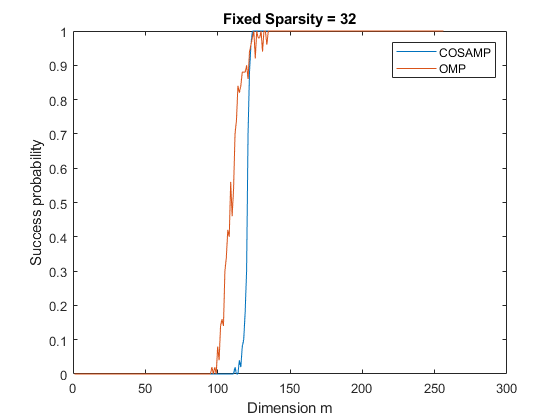

close all
clear all
load('s60_M4_COSAMP.mat')
plot(probability)
hold on
load('s60_M4_OMP.mat')
plot(probability)

title('Fixed Sparsity = 32')
legend('COSAMP','OMP')
xlabel('Dimension m');
ylabel('Success probability');

# **COSAMP ALGORITHM**

function [x_sharp, residual_plot, current_iteration]=COSAMP(A,y,m,N,s,nb_iterations,x)
x_sharp=zeros(N,1);
residual_plot=zeros(nb_iterations,1);
% for k=1:nb_iterations
current_iteration = 0;
error=10;
while (error > 10e-6) && (current_iteration<120)
    
    %CoSaMP 1: U^(n+1) = supp(x^n) Union L_2s(A*(y-Ax^n))
    residual=y-A*x_sharp;
    U = union(find(x_sharp),L_s(A'*residual,2*s));
    U = unique(U,'rows',"sorted");
    
    %CoSaMP 2: u^(n+1) in argmin{|y-Az|_2 : supp(z) subset U^(n+1)}
    A_U = restrict_matrix(A,U,m);
    
    z = A_U\y;
    %     z = lsqr(A_U,y);
    u = unrestrict_vector(z,U,N);
    
    %CoSaMP 3: x^(n+1) = H_s(u^(n+1))
    H = L_s(u,s);
    x_sharp = H_s(H,u,N);
    %     residual_plot(k,1) = norm(A*x_sharp-y);
    error=norm(x-x_sharp);
    current_iteration=current_iteration+1;
    %     residual_plot(k,1) = norm(x-x_sharp)/norm(x);
end
end


# **COSAMPL ALGORITHM (in levels)**

function [x_sharp,current_iteration]= COSAMPL(A,y,m,N,s,M,x)
x_sharp=zeros(N,1);
current_iteration = 0;
error=10;
while (error > 10e-6) && (current_iteration<120)
    
    %CoSaMP 1: U^(n+1) = supp(x^n) Union L_2s(A*(y-Ax^n))
    residual=y-A*x_sharp;
    U = union(find(x_sharp),L_s_M(A'*residual,2*s,M));
    U = unique(U,'rows',"sorted");
    
    %CoSaMP 2: u^(n+1) in argmin{|y-Az|_2 : supp(z) subset U^(n+1)}
    A_U = restrict_matrix(A,U,m);
    
    z = A_U\y;
    %     z = lsqr(A_U,y);
    u = unrestrict_vector(z,U,N);
    
    %CoSaMP 3: x^(n+1) = H_s(u^(n+1))
    H = L_s_M(u,s,M);
    x_sharp = H_s_M(H,u,N);
    %     residual_plot(k,1) = norm(A*x_sharp-y);
    error=norm(x-x_sharp);
    current_iteration=current_iteration+1;
    %     residual_plot(k,1) = norm(x-x_sharp)/norm(x);
end
end

# **OMP ALGORITHM**

function [x_sharp, residual_plot,k] = OMP(A,y,N,m,nb_iterations)
residual_plot=zeros(nb_iterations,1);
residual=y;S=[];
for k=1:nb_iterations
    vals=A'*(residual);
    [M,j] = max(abs(vals));
    S(length(S)+1,1)=j;
    S=unique(S,'rows',"sorted");
    A_s=restrict_matrix(A,S,m);
    z=A_s\y;
    residual=y-A_s*z;
    residual_plot(k,1)=norm(residual);
end

x_sharp=unrestrict_vector(z,S,N);

end


# **OMPL ALGORITHM**

function [x_sharp,k] = OMPL(A,y,s,M,m,N)
residual=y;S=[];
nb_iterations=sum(s,'all');
for k=1:nb_iterations+nb_iterations/2
    vals=A'*(residual);
    [s,j]=argmax(vals,s,M,S);
    S=union(S,j);
    S=unique(S,'rows',"sorted");
    A_s=restrict_matrix(A,S',m);
    z=A_s\y;
    x_sharp=unrestrict_vector(z,S',N);
    %remove smallest entry of z here when sum(s,'all')=0, to decide which
    %is the smaller, do A*resid, remoce that one
    residual=y-A*x_sharp;
end
end



# **AUX FUNCTIONS**



function plot_residuals_vs_iterations(residual,type)
semilogy(residual)
ylim([10e-16 10e-6])
title('Residual as a function of k using')
legend('2-norm of residual')
xlabel('k iterations')
ylabel('$\|y-Ax^{(k)}\|_2$','Interpreter','latex')
end


function max_index_set = L_s_M(z,s,M)
M=union(0,M);
max_index_set =zeros(sum(s,'all'),1);
counter = 1;
for i=2:length(M)
    lower_bound = (M(i-1)+1);
    upper_bound= M(i);
    current_level=abs(z(lower_bound:upper_bound));
    current_sparsity_level=s(i-1);
    for k=1:current_sparsity_level
        [Max,j]=max(current_level);
        max_index_set(counter,1)=j+M(i-1);
        current_level(j)=0;
        counter = counter+1;
    end
    
end
max_index_set=sort(max_index_set, 'ascend');
end


function [s,j] = argmax(z,s,M,S)
M=union(0,M);
for i=2:length(M)
    lower_bound = (M(i-1)+1);
    upper_bound = M(i);
    if(sum(s,'all')==0)
        z_restricted=zeros(length(S),1);
        for a=1:length(S)
            z_restricted(a)=z(S(a));
        end
        %         z_removed_index=H_s(S,z,256);
        [m,index]=min(abs(z_restricted));
        %         z_restricted(index)=0;
        index_to_remove=S(index);
        for n=1:length(M)
            if(index_to_remove>M(n))
            else
                s(n-1)=s(n-1)+1;
                break
            end
        end
    end
    if(s(i-1) == 0)
        z(lower_bound:upper_bound)=0;
    end
end
[maximum,j]=max(abs(z));
for i=1:length(M)
    if(j>M(i))
    else
        s(i-1)=s(i-1)-1;
        break
    end
end
end


function coherance = check_coherance(A)
dimension_A=size(A);
j=1;
total_inner_products=nchoosek(dimension_A(2),2);
inner_products=zeros(total_inner_products,1);
for i=1:dimension_A(2)-1
    for k=i+1:dimension_A(2)
        inner_products(j,1)=dot(A(:,i),A(:,k));
        j=j+1;
    end
end
[M,index]=max(abs(inner_products));
coherance=M;
end

function RIC=check_RIP(RIC,A,x)
if (1-RIC)*norm(x)^2 <=norm(A*x)^2 && norm(A*x)^2 <=  (1+RIC)*norm(x)^2
    RIC=true;   %(1)
else
    RIC=false;  %(0)
end
end

function max_index_set = L_s(z,s)
max_index_set =[];
for i=1:s
    z=abs(z);
    [M,j]=max(z);
    max_index_set(length(max_index_set)+1,1)=j;
    z(j)=0;
end
% max_index_set=unique(max_index_set,'rows',"sorted");
max_index_set=sort(max_index_set, 'ascend');
end

function x = H_s(H,u,N)
x=zeros(N,1);
for i=1:length(H)
    x(H(i))=u(H(i));
end
end

function matrix_to_restrict = restrict_matrix(matrix, index_set,m)
% index_set=index_set';
matrix_to_restrict = zeros(m,length(index_set));
for i=1:length(index_set)
    matrix_to_restrict(:,i)=matrix(:,index_set(i,1));
end
end

function vector_to_unrestrict =unrestrict_vector(vector,index_set,N)
vector_to_unrestrict=zeros(N,1);
for i=1:length(index_set)
    vector_to_unrestrict(index_set(i,1))=vector(i,1);
end
end

function y=generate_signal(m,N)
y=zeros(m,1);
for i=1:m
    y(i,1)=sin((12*pi)*((i-1)/N- 1.1)) + 2*max(1-abs(i/6 -7),0);
end

end


function x = H_s_M(H,u,N)
x=zeros(N,1);
for i=1:length(H)
    x(H(i))=u(H(i));
end
end

# **cosamp built in**

function [x,r,normR,residHist, errHist,kk] = CoSaMP( A, b, k, errFcn, opts )
% x = CoSaMP( A, b, k )
% Outputs:
%   'x' is the k-sparse estimate of the unknown signal
%   'r' is the residual b - A*x
%   'normR' = norm(r)
%   'residHist'     is a vector with normR from every iteration
%   'errHist'       is a vector with the outout of errFcn from every iteration
%
% Inputs:
%   'A'     is the measurement matrix
%   'b'     is the vector of observations
%   'k'     is the estimate of the sparsity (you may wish to purposefully
%              over- or under-estimate the sparsity, depending on noise)
%              N.B. k < size(A,1) is necessary, otherwise we cannot
%                   solve the internal least-squares problem uniquely.
%   'errFcn'    (optional; set to [] to ignore)

if nargin < 5, opts = []; end
if ~isempty(opts) && ~isstruct(opts)
    error('"opts" must be a structure');
end

    function out = setOpts( field, default )
        if ~isfield( opts, field )
            opts.(field)    = default;
        end
        out = opts.(field);
    end
    
    printEvery  = setOpts( 'printEvery', 1000 );
    maxiter     = setOpts( 'maxiter', 1000 );
    normTol     = setOpts( 'normTol', 1e-10 );
    addK        = round(setOpts( 'addK', 2*k) );
    support_tol = setOpts( 'support_tol', 1e-10 );
    
    
    if nargin < 5 || isempty(printEvery)
        printEvery  = round(k,maxiter);
    end
    
    if nargin < 4
        errFcn = [];
    elseif ~isempty(errFcn) && ~isa(errFcn,'function_handle')
        error('errFcn input must be a function handle (or leave the input empty)');
    end
    
    At  = @(x) A'*x;
    
    
    
    % -- Intitialize --
    % start at x = 0, so r = b - A*x = b
    r           = b;
    Ar          = At(r);
    N           = size(Ar,1);       % number of atoms
    M           = size(r,1);        % size of atoms
    if k > M/3
        error('K cannot be larger than the dimension of the atoms');
    end
    x           = zeros(N,1);
    ind_k       = [];
    
    % indx_set    = zeros(k,1);  % created on-the-fly
    % A_T         = zeros(M,k);
    residHist   = zeros(k,1);
    errHist     = zeros(k,1);
    
    fprintf('Iter,   |T|,  Resid');
    if ~isempty(errFcn)
        fprintf(',   Error');
    end
    
    for kk = 1:maxiter
        % -- Step 1: find new index and atom to add
        y_sort      = sort( abs(Ar),'descend');
        cutoff      = y_sort(addK); % addK is typically 2*k
        cutoff      = max( cutoff, support_tol );
        ind_new     = find( abs(Ar) >= cutoff );
        % -- Merge:
        T    = union( ind_new, ind_k );
        % -- Step 2: update residual
        RHS     = b;
        
        % -- solve for x on the suppor set "T"
        %         x_T=lsqr(A(:,T),RHS);
        x_T = A(:,T)\RHS;   % more efficient; equivalent to pinv when underdetermined.
        %         x_T     = pinv( A(:,T) )*RHS;
        
        
        % Prune x to keep only "k" entries:
        cutoff  = findCutoff(x_T, k);
        Tk      = find( abs(x_T) >= cutoff );
        % This is assuming there are no ties. If there are,
        %    from a practical standpoint, it probably doesn't
        %    matter much what you do. So out of laziness, we don't worry about it.
        ind_k   = T(Tk);
        x       = 0*x;
        x( ind_k ) = x_T( Tk );
        r_old   = r;
        % don't do a full matrix-vector multiply, just use necessary columns
        r   = b - A(:,ind_k)*x_T( Tk );
        
        % -- Print some info --
        PRINT   = ( ~mod( kk, printEvery ) || kk == maxiter );
        normR   = norm(r);
        STOP    = false;
        if normR < normTol || norm( r - r_old ) < normTol
            STOP    = true;
            PRINT   = true;
        end
        if ~isempty(errFcn)
            er  = errFcn(x);
            errHist(kk)     = er;
        end
        if PRINT
            fprintf('%4d, %4d, %.2e', kk, length(T), normR);
            if ~isempty(errFcn)
                fprintf(', %.2e',er);
            end
            fprintf('\n');
        end
        
        residHist(kk)   = normR;
        
        if STOP
            disp('Reached stopping criteria');
            break;
        end
        
        if kk < maxiter
            Ar  = At(r); % prepare for next round
        end
        
    end
    
end % -- end of main function

function tau = findCutoff( x, k )
% finds the appropriate cutoff such that after hard-thresholding,
% "x" will be k-sparse
x   = sort( abs(x),'descend');
if k > length(x)
    tau = x(end)*.999;
else
    tau  = x(k);
end
end
